Time evolution using original Non-linear function

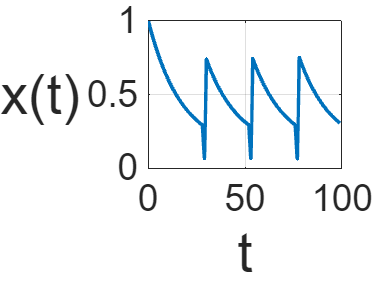

clc;clear;close all;
t_steps = 100;
x = zeros(t_steps,1);
x(1) = 1;
for i = 1:t_steps-1
    x(i+1) = F_x(x(i));
end
figure;
plot(0:t_steps-1,x,"LineWidth",2)
grid on;
set(gca,"FontSize",20)
xlabel("t","FontSize",30)
ylabel("x(t)","FontSize",30,"Rotation",0)

Obtaining approximate koopman matrix for linear propagation in lifted space

m = 557; % No. of observables
Xi = zeros(m,t_steps);
x_0 = 0;
Xi(1,1) = 1; 
for i = 1:(m-1)/2
    Xi(2*i,1) = cos(2*pi*i*x_0);
    Xi(2*i+1,1) = sin(2*pi*i*x_0);
end
A_inprod = lin_koopman(m);
for i = 1:t_steps-1
    Xi(:,i+1) = A_inprod*Xi(:,i);
end
x_est = recover_x(Xi);

Plotting Koopman estimated states with actual states

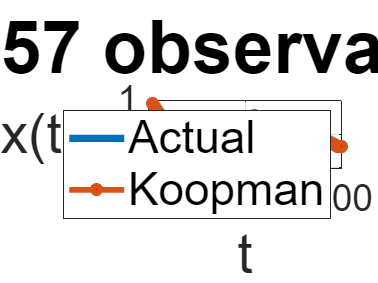

plot(2:t_steps,x(2:end),LineWidth=4)
hold on
plot(2:t_steps, x_est(2:end), '-o', 'MarkerSize', 4, 'MarkerFaceColor', 'red', 'LineWidth', 3.2)
legend("Actual","Koopman","FontSize",25)
hold off
grid on;
set(gca,"FontSize",20)
xlabel("t","FontSize",30)
title("557 observables","FontSize",40)
ylabel("x(t)","FontSize",30,"Rotation",0)

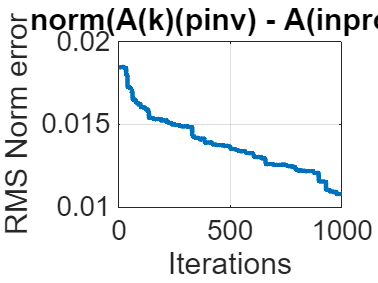

close all;
npoints = 3*m;
x1 = rand(npoints,1); X1 = zeros(m,npoints); Y1 = zeros(m,npoints);
X1(1,:) = 1; Y1(1,:) = 1;
y1 = F_x(x1);
for i = 1:npoints
    for j = 1:(m-1)/2
        X1(2*j,i) = cos(2*pi*j*x1(i));
        X1(2*j+1,i) = sin(2*pi*j*x1(i));
        Y1(2*j,i) = cos(2*pi*j*y1(i));
        Y1(2*j+1,i) = sin(2*pi*j*y1(i));
    end
end
Cm(1,1) = 1;
for i = 2:2:m-1
    Cm(i, i) = 0.5; Cm(i, i+1) = 0.5;
    Cm(i+1, i) = -0.5i; Cm(i+1, i+1) = 0.5i;
end

Cm_inv(1,1) = 1;
for i = 2:2:m-1
    Cm_inv(i, i) = 1; Cm_inv(i, i+1) = 1i;
    Cm_inv(i+1, i) = 1; Cm_inv(i+1, i+1) = -1i;
end

Xtild1 = Cm_inv*X1; Ytild1 = Cm_inv*Y1;
XXT_inv = pinv(Xtild1*Xtild1'); 
Abar1 = Ytild1*pinv(Xtild1);
Abar = Abar1;
A1 = Cm_inv*A_inprod*Cm;

for iter = 1:1000
    XXT_inv_prev = XXT_inv;
    Abar_prev = Abar;
    x = rand; y=F_x(x);cx=zeros(m,1);cy=zeros(m,1);
    cx(1) = 1; cy(1) = 1;
    for i = 1:(m-1)/2
        cx(2*i) = cos(2*pi*i*x);
        cx(2*i+1) = sin(2*pi*i*x);
        cy(2*i) = cos(2*pi*i*y);
        cy(2*i+1) = sin(2*pi*i*y);
    end
    ctildx = Cm_inv*cx; ctildy = Cm_inv*cy;
    scalar = 1 + ctildx'*XXT_inv_prev*ctildx;
    rank1_upd = eye(m) - (ctildx*ctildx')*XXT_inv_prev/scalar; 
    XXT_inv = XXT_inv_prev*rank1_upd;
    Abar = (Abar_prev + ctildy*ctildx'*XXT_inv_prev)*rank1_upd;
    Norms(iter) = rms(Abar(:)-A1(:));
end
figure;
plot(1:length(Norms),(Norms),"LineWidth",2.5)
xlabel("Iterations","FontSize",20)
ylabel("RMS Norm error","FontSize",20)
title("norm(A(k)(pinv) - A(inprod))","FontSize",20)
grid on;
set(gca,"FontSize",15)

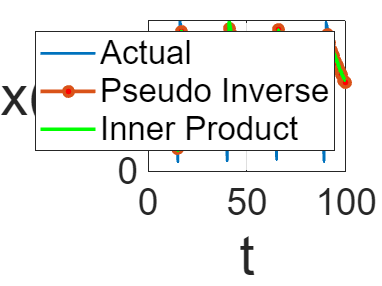

clf
t_steps = 100;
x = zeros(t_steps,1);
x_0 = 0.5;
x(1) = x_0;
Xi = zeros(m,t_steps);
Xi(1,1) = 1; 
for i = 1:(m-1)/2
    Xi(2*i,1) = cos(2*pi*i*x_0);
    Xi(2*i+1,1) = sin(2*pi*i*x_0);
end
X_ki = Xi;
A_pinv = real(Cm*Abar*Cm_inv);
for i = 1:t_steps-1
    Xi(:,i+1) = A_pinv*Xi(:,i);
    X_ki(:,i+1) = A_inprod*X_ki(:,i);
end

for i = 1:t_steps-1
    x(i+1) = F_x(x(i));
end
x_est = recover_x(Xi);
x_kest = recover_x(X_ki);

figure
plot(1:t_steps,x,'LineWidth', 1.5)
hold on
plot(1:t_steps,x_est, '-o', 'MarkerSize', 5, 'MarkerFaceColor', 'red', 'LineWidth', 2)
plot(1:t_steps,x_kest, 'LineWidth', 2,'Color',"g")
legend('Actual','Pseudo Inverse','Inner Product')
grid on;
set(gca,"FontSize",20)
xlabel("t","FontSize",30)
ylabel("x(t)","FontSize",30,"Rotation",0)

title("Koopman Comparison (557 observables)")

## Single Control Input


$$x_{t+1} = F(x_t) + \alpha u_t
\\
Lift ~ h(x,u) =[F(x)+\alpha u ; 0]  \text{ to get A, such that}
\\
z_{t+1} = \tilde Az_t + \tilde B u_t \text{  , where }z = g(x_t)$$


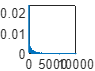

clear;close all;
m = 257;
npoints = 3*m;
alpha = 0.1;
x1 = rand(npoints,1); u1 = 2*rand(npoints,1)-1; 
y1 = F_x(x1) + alpha*u1;
p1 = [x1;u1];
pnext1 = [y1;0];

X1 = zeros(m,npoints); Y1 = zeros(m,npoints);
X1(1,:) = 1; Y1(1,:) = 1;
for i = 1:npoints
    for j = 1:(m-1)/2
        X1(2*j,i) = cos(2*pi*j*x1(i));
        X1(2*j+1,i) = sin(2*pi*j*x1(i));
        Y1(2*j,i) = cos(2*pi*j*y1(i));
        Y1(2*j+1,i) = sin(2*pi*j*y1(i));
    end
end
X1 = [u1';X1]; Y1 = [zeros(1,npoints);Y1];
Cm(1,1) = 1;
for i = 2:2:m-1
    Cm(i, i) = 0.5; Cm(i, i+1) = 0.5;
    Cm(i+1, i) = -0.5i; Cm(i+1, i+1) = 0.5i;
end

Cm_inv(1,1) = 1;
for i = 2:2:m-1
    Cm_inv(i, i) = 1; Cm_inv(i, i+1) = 1i;
    Cm_inv(i+1, i) = 1; Cm_inv(i+1, i+1) = -1i;
end

XXT_inv1 = pinv(X1*X1'); 
A1 = Y1*pinv(X1);
XXT_inv = XXT_inv1;
A = A1;

for iter = 1:10000
    XXT_inv_prev = XXT_inv;
    A_prev = A;
    x = rand; u = 2*rand-1; y=F_x(x)+alpha*u;cx=zeros(m,1);cy=zeros(m,1);
    cx(1) = 1; cy(1) = 1;
    for i = 1:(m-1)/2
        cx(2*i) = cos(2*pi*i*x);
        cx(2*i+1) = sin(2*pi*i*x);
        cy(2*i) = cos(2*pi*i*y);
        cy(2*i+1) = sin(2*pi*i*y);
    end
    cx = [u;cx]; cy = [0;cy];
    scalar = 1 + cx'*XXT_inv_prev*cx;
    rank1_upd = eye(m + 1) - (cx*cx')*XXT_inv_prev/scalar; 
    XXT_inv = XXT_inv_prev*rank1_upd;
    A = (A_prev + cy*cx'*XXT_inv_prev)*rank1_upd;
    Norms(iter) = rms(A(:)-A_prev(:));
end
plot(1:length(Norms),(Norms))

Atilde = A(2:end,2:end);
Btilde = A(2:end,1);

Trying out paper method, where


$$x_{t+1} = F(x_t) + \alpha u_t
\\
Lift ~ h(x,u) =[F(x)+\alpha u ; u]  \text{ to get A, such that}
\\
z_{t+1} = \tilde Az_t + \tilde B u_t \text{  , where }z = g(x_t)$$


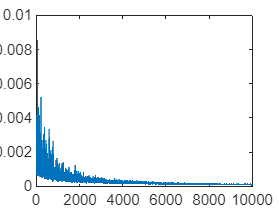

clear;close all;
m = 257;
npoints = 3*m;
alpha = 0.1;
x1 = rand(npoints,1); u1 = 2*rand(npoints,1)-1; 
u_old1 = 
y1 = F_x(x1) + alpha*u1;
p1 = [x1;u1];
pnext1 = [y1;u1];

X1 = zeros(m,npoints); Y1 = zeros(m,npoints);
X1(1,:) = 1; Y1(1,:) = 1;
for i = 1:npoints
    for j = 1:(m-1)/2
        X1(2*j,i) = cos(2*pi*j*x1(i));
        X1(2*j+1,i) = sin(2*pi*j*x1(i));
        Y1(2*j,i) = cos(2*pi*j*y1(i));
        Y1(2*j+1,i) = sin(2*pi*j*y1(i));
    end
end
X1 = [X1;u1'  ]; Y1 = [Y1;u1'];
Cm(1,1) = 1;
for i = 2:2:m-1
    Cm(i, i) = 0.5; Cm(i, i+1) = 0.5;
    Cm(i+1, i) = -0.5i; Cm(i+1, i+1) = 0.5i;
end

Cm_inv(1,1) = 1;
for i = 2:2:m-1
    Cm_inv(i, i) = 1; Cm_inv(i, i+1) = 1i;
    Cm_inv(i+1, i) = 1; Cm_inv(i+1, i+1) = -1i;
end

XXT_inv1 = pinv(X1*X1'); 
A1 = Y1*pinv(X1);
XXT_inv = XXT_inv1;
A = A1;

for iter = 1:10000
    XXT_inv_prev = XXT_inv;
    A_prev = A;
    x = rand; u = 2*rand-1; y=F_x(x)+alpha*u;cx=zeros(m,1);cy=zeros(m,1);
    cx(1) = 1; cy(1) = 1;
    for i = 1:(m-1)/2
        cx(2*i) = cos(2*pi*i*x);
        cx(2*i+1) = sin(2*pi*i*x);
        cy(2*i) = cos(2*pi*i*y);
        cy(2*i+1) = sin(2*pi*i*y);
    end
    cx = [cx;u]; cy = [cy;u];
    scalar = 1 + cx'*XXT_inv_prev*cx;
    rank1_upd = eye(m + 1) - (cx*cx')*XXT_inv_prev/scalar; 
    XXT_inv = XXT_inv_prev*rank1_upd;
    A = (A_prev + cy*cx'*XXT_inv_prev)*rank1_upd;
    Norms(iter) = rms(A(:)-A_prev(:));
end
plot(1:length(Norms),(Norms))

Atilde = A(1:end-1,1:end-1);
Btilde = A(1:end-1,end);

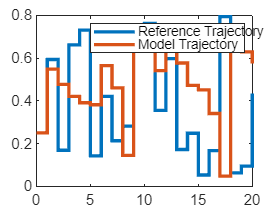

N = 20;
x_traj = rand(N+1,1); % Reference Trajectory
Z_traj=zeros(m,N+1);
Z_traj(1,:) = 1; 

for i = 1:N + 1
    for j = 1:(m-1)/2
        Z_traj(2*j,i) = cos(2*pi*j*x_traj(i));
        Z_traj(2*j+1,i) = sin(2*pi*j*x_traj(i));
    end
end

for i = 1:N
    u(i) = pinv(Btilde)*(Z_traj(:,i+1)-Atilde*Z_traj(:,i));
end

x_contr = zeros(N+1,1);x_contr(1) = x_traj(1);

for i = 1:N
    x_contr(i+1) = F_x(x_contr(i))+alpha*u(i);
end
figure
stairs(0:N,x_traj,LineWidth=2)
hold on
stairs(0:N,x_contr,LineWidth=2)
legend("Reference Trajectory","Model Trajectory")

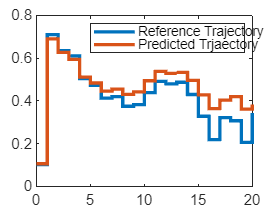


nref = 20;
x0 = rand; % Reference Trajectory
xref = zeros(nref+1,1);
xref(1) = x0;
u_ref = 2*rand(nref,1)-1;
for i=1:nref
    xref(i+1) = F_x(xref(i)) + alpha*u_ref(i);
end

Z = zeros(m,nref + 1); 
Z(1,:) = 1; 
for j = 1:(m-1)/2
    Z(2*j,1) = cos(2*pi*j*x0);
    Z(2*j+1,1) = sin(2*pi*j*x0);
end
% for i = 1:nref + 1
%     for j = 1:(m-1)/2
%         Z(2*j,i) = cos(2*pi*j*x_ref(i));
%         Z(2*j+1,i) = sin(2*pi*j*x_ref(i));
%     end
% end

for i = 1:nref
    Z(:,i+1) = Atilde*Z(:,i) + Btilde*u_ref(i);
end
x_model = recover_x(Z);
figure
stairs(0:nref,xref,LineWidth=2);
hold on
stairs(0:nref,x_model,LineWidth=2);
legend("Reference Trajectory","Predicted Trjaectory")

% stairs(0:nref-1,u_act);
% hold on
% stairs(0:nref-1,u_model);
% legend("Actual Control Input","Model Control Input")
% title("Control input variation in time")

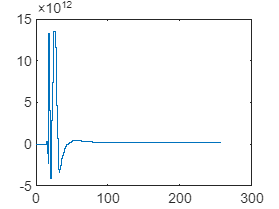


N = 257;
x0 = rand;x_N = 0.5;
Z0 = zeros(m,1);Z_N = zeros(m,1); 
Z_N(1) = 1; Z0(1) = 1;
for j = 1:(m-1)/2
    Z0(2*j,1) = cos(2*pi*j*x0);
    Z0(2*j+1,1) = sin(2*pi*j*x0);
end
for j = 1:(m-1)/2
    Z_N(2*j,1) = cos(2*pi*j*x_N);
    Z_N(2*j+1,1) = sin(2*pi*j*x_N);
end
C = zeros(m,N);
for i = 1:N
    C(:,i) = Atilde^(i-1)*Btilde;
end
u = pinv(C)*(Z_N-Atilde^N*Z0);
% for i = 1:N
%     Z0(:,i+1) = Atilde*Z0(:,i) + Btilde*u(i);
% end
% x_contr = recover_x(Z0);
x_mod = zeros(N,1);
x_mod(1) = x0;
for i = 1:N
    x_mod(i+1) = F_x(x_mod(i)) + u(i);
end
figure
stairs(0:N,x_mod);

% Compute eigenvalues of Atilde
eigenvalues = eig(Atilde);

% Initialize an array to store controllable eigenvalues
controllableEigenvalues = [];

% Check controllability for each eigenvalue
for i = 1:length(eigenvalues)
    lambda = eigenvalues(i);
    % Check if the controllability matrix is full rank
    if rank(Atilde - lambda*eye(size(Atilde)), Btilde) == size(Atilde, 1)
        % If full rank, the eigenvalue is controllable
        controllableEigenvalues = [controllableEigenvalues; lambda];
    end
end



# 2) Taking another system, without hybrid dynamics


$$f(x) = \frac{1}{1 + e^{-10(x - 0.5)}}$$


clear;close all;
F_sigmoid =  @(x) 1 ./ (1 + exp(-10 * (x - 0.5)));
m = 257;
npoints = 3*m;
alpha = 0.1;
x1 = rand(npoints,1); u1 = 2*rand(npoints,1)-1; 
y1 = F_sigmoid(x1) + alpha*u1;
p1 = [x1;u1];
pnext1 = [y1;u1];

X1 = zeros(m,npoints); Y1 = zeros(m,npoints);
X1(1,:) = 1; Y1(1,:) = 1;
for i = 1:npoints
    for j = 1:(m-1)/2
        X1(2*j,i) = cos(2*pi*j*x1(i));
        X1(2*j+1,i) = sin(2*pi*j*x1(i));
        Y1(2*j,i) = cos(2*pi*j*y1(i));
        Y1(2*j+1,i) = sin(2*pi*j*y1(i));
    end
end
X1 = [x1';X1;u1']; Y1 = [y1';Y1;u1'];
Cm(1,1) = 1;
for i = 2:2:m-1
    Cm(i, i) = 0.5; Cm(i, i+1) = 0.5;
    Cm(i+1, i) = -0.5i; Cm(i+1, i+1) = 0.5i;
end

Cm_inv(1,1) = 1;
for i = 2:2:m-1
    Cm_inv(i, i) = 1; Cm_inv(i, i+1) = 1i;
    Cm_inv(i+1, i) = 1; Cm_inv(i+1, i+1) = -1i;
end

XXT_inv1 = pinv(X1*X1'); 
A1 = Y1*pinv(X1);
XXT_inv = XXT_inv1;
A = A1;

for iter = 1:10000
    XXT_inv_prev = XXT_inv;
    A_prev = A;
    x = rand; u = 2*rand-1; y=F_sigmoid(x)+alpha*u;cx=zeros(m,1);cy=zeros(m,1);
    cx(1) = 1; cy(1) = 1;
    for i = 1:(m-1)/2
        cx(2*i) = cos(2*pi*i*x);
        cx(2*i+1) = sin(2*pi*i*x);
        cy(2*i) = cos(2*pi*i*y);
        cy(2*i+1) = sin(2*pi*i*y);
    end
    cx = [x;cx;u]; cy = [y;cy;u];
    scalar = 1 + cx'*XXT_inv_prev*cx;
    rank1_upd = eye(m + 2) - (cx*cx')*XXT_inv_prev/scalar; 
    XXT_inv = XXT_inv_prev*rank1_upd;
    A = (A_prev + cy*cx'*XXT_inv_prev)*rank1_upd;
    Norms(iter) = rms(A(:)-A_prev(:));
end
plot(1:length(Norms),(Norms))
Atilde = A(1:end-1,1:end-1);
Btilde = A(1:end-1,end);

t_steps = 100;
x = zeros(t_steps,1);
x(1) = 0.2;
for i = 1:t_steps-1
    x(i+1) = F_sigmoid(x(i));
end

Xi = zeros(m,t_steps);
x_0 = x(1);
Xi(1,1) = 1; 
for i = 1:(m-1)/2
    Xi(2*i,1) = cos(2*pi*i*x_0);
    Xi(2*i+1,1) = sin(2*pi*i*x_0);
end
Xi = [zeros(1,t_steps);Xi];
Xi(1,1) = x_0;
for i = 1:t_steps-1
    Xi(:,i+1) = Atilde*Xi(:,i);
end
%x_est = recover_x(Xi);
x_est = Xi(1,:);
figure
plot(1:t_steps,x,'LineWidth',2)
hold on
plot(1:t_steps,x_est,'LineWidth',2)
legend("Actual Trajectory","Predicted Trajectory")